Controllo se è rimasta aperta la porta seriale

if(exist('STM32_ser', 'var'))
    delete(STM32_ser);
end

baudrate = 1000000

baudrate = 1000000

porte_libere = serialportlist("available")

porte_libere = "COM8"

STM32_ser = serialport(porte_libere(end), baudrate , Timeout=2);

Connetto alla seriale

buff_size = 400;
measures = 2;

Numero_Misure = 300

Numero_Misure = 300

l =  buff_size*measures

l = 800

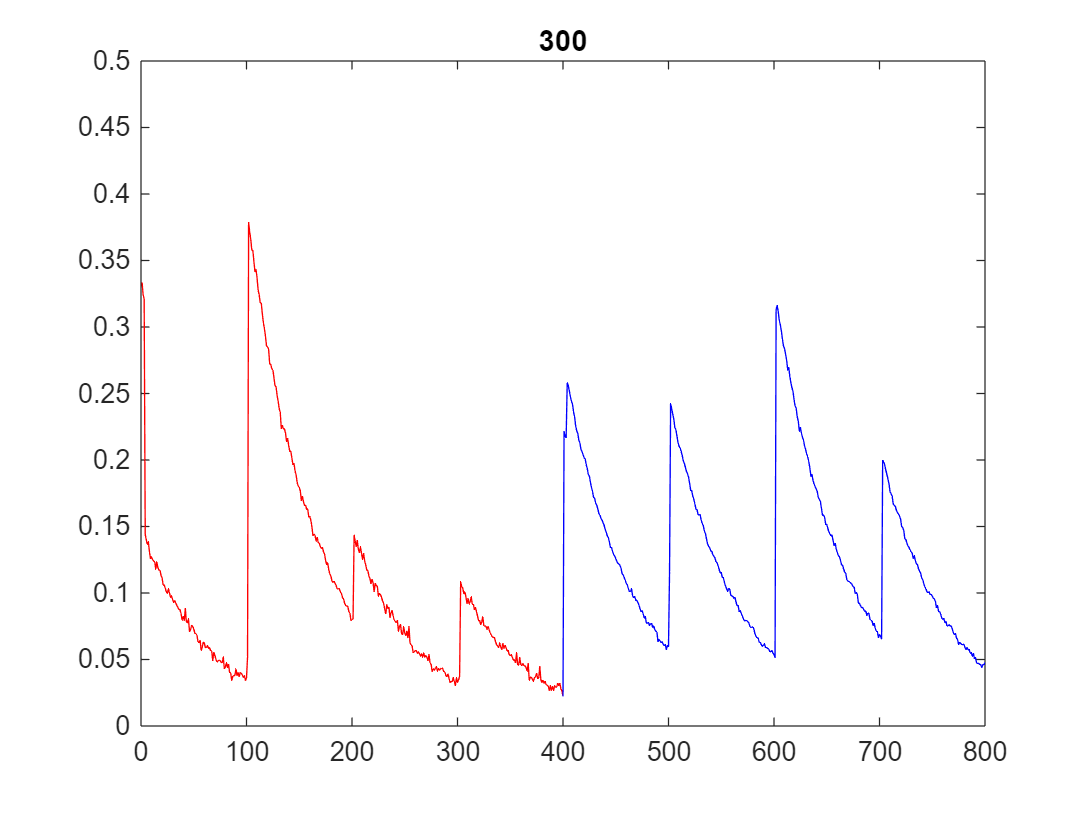

data_buffer = zeros(Numero_Misure, buff_size);
index = 1;

while (index < Numero_Misure+1)
% while 1

    STM32_ser.write('?','char');
    data = STM32_ser.read(l,'uint16') ./ 2^16 * 3.3;

    figure(1);
    plot(1:l/2, data(1:l/2), 'r', l/2:l, data(l/2:l), 'b' )
    ylim([0,.5]);
    title(index);

    data_buffer(index, :) = data(1:buff_size);
    index = index +1;
    drawnow
end

max_val = zeros(0,Numero_Misure);
for i=1:Numero_Misure
    max_val(i) = max(data_buffer(i,15));
end

max_val2 = zeros(0,Numero_Misure);
for i=1:Numero_Misure
    max_val2(i) = max(data_buffer(i,200+15));
end

Index in position 2 exceeds array bounds. Index must not exceed 400.

histogram(max_val, 100, 'red')
histogram(max_val2, 100, 'blue')